clc;
clear;
close all;

## 添加路径

addpath('plane wave\')

## 参数设置

# Gaussian Beam

lambda=561e-6;
beamSize=1.8;       %初始高斯光束腰斑直径
beamAmp=1;
noise=0;
beamStd=beamSize/2.85;
beam=GaussianBeam(beamAmp,beamStd,lambda);
color=wavelength2color(lambda*10^6, 'gammaVal', 2.2, 'maxIntensity', 1, 'colorSpace', 'rgb');
R=linspace(0,color(1),65535)';
G=linspace(0,color(2),65535)';
B=linspace(0,color(3),65535)';
mymap=[R G B];
colormap(mymap)

# MLA

rla=-0.63;% 透镜1的曲率半径           
d = 0.15;              % 透镜单元边长
t = 2;            % 透镜厚度
N=40;% 微透镜单元采样点数
material={"SK-1310"};
MLA1=Lens([rla,-rla],t,d,material,lambda);
num=floor(beamStd/d*5);            %数量
if num==0
    num=1;
end
area1 = num*d;           % 光场的面积
area2=25;
area3=25;
rate=(d/N);           %采样率（global）
area2=findClosestDivisible(area2,rate);
peak=0;
SD=0;
uniformity=0;
beams= GaussianBeam.defocused(beam,10,N*num,rate);
I_sum=sum(abs(beams).^2,'all');

# Ex-MLA

rla_ex = -1.6;            % 透镜1的曲率半径
d_ex = 0.18;              % 透镜单元边长
t_ex=1;
MLA2=Lens([rla_ex inf],t_ex,d_ex,material,lambda);

aperture=drawCircle(23/2/rate,0,0,round(area2/rate),round(area2/rate));

distance1 = 298.739;   % 投影距离
distance2 = 301.583;
distance3 = 2.759;

# Fourier Lens

rfl1 = -557.400;            % 傅里叶透镜的曲率半径（胶合透镜）
rfl2 = -137.090;
rfl3 = 165.2;
dfl = 40;              % 傅里叶透镜直径
Dfl = area2;              %采样区域
tfl = [2,4];            % 傅里叶透镜厚度
material_fl={'SF2','N-BK7'};

FL=Lens([rfl1,rfl2,rfl3],tfl,dfl,material_fl,lambda);

# Diffuser

rpm=58000;%电机转速(圈每分钟)
rpus=rpm/60/1000/1000;
radius_diffuser=18;%散射片半径mm
velocity=2*pi*rpus*radius_diffuser;
deltat=1;%
T=100;%积分时间（μs）
times=floor(T/deltat);
diffuserAngle=0.5;   %散射片散射角度
diffuser=Diffuser(diffuserAngle,lambda);
phase=Diffuser.generateDiffuser(diffuser,rate,[round(velocity*T/rate)+size(beams,1),N*num]);

# Objective Lens

n_oil=1;
f_TL=200;
beta=60;
f_OBJ=f_TL/beta;
NA=1.49;
rate2=1/area3*lambda*f_TL;%管镜焦面采样率
area4=(rate2*area3/rate);%管镜焦面计算大小
rate3=1/area4*lambda*f_OBJ/n_oil;%样品面采样率
rP=f_OBJ*NA;
mask=drawCircle(rP/rate2,0,0,round(area4/rate2),round(area4/rate2));
I=zeros(round(area3/rate));

## 生成透镜相位

%%生成匀光微透镜阵列厚度函数
Lens.lensArrayThickFcn(MLA1,N,num,'hexagon',0);
%% 生成傅里叶透镜厚度函数
Lens.lensThickFcn(FL,Dfl,round(area2/rate));
%% 生成激发微透镜阵列厚度函数
lensArray.lensArrayThickFcn2(MLA2,d_ex/rate,area2/d_ex,'hexagon',5.8,(d_ex-0.01)*0.7,0)

Lens.lensSingle(MLA1)
Lens.lensSingle(FL);
Lens.lensSingle(MLA2);

beams=single(beams);
N=single(N);
num= single(num);
Diffuser.diffuserSingle(diffuser)
rate= single(rate);
lambda= single(lambda);
distance1= single(distance1);
distance2= single(distance2);
distance3= single(distance3);
area1= single(area1);
area2= single(area2);
area3= single(area3);
if canUseGPU
    Lens.lensGPUArray(MLA1)
    Lens.lensGPUArray(FL)
    Lens.lensGPUArray(MLA2);
    beams=gpuArray(beams);
    N= gpuArray(N);
    num= gpuArray(num);
    Diffuser.diffuserGPUArray(diffuser)
    rate= gpuArray(rate);
    lambda= gpuArray(lambda);
    distance1= gpuArray(distance1);
    distance2= gpuArray(distance2);
    distance3= gpuArray(distance3);
    area1= gpuArray(area1);
    area2= gpuArray(area2);
    area3= gpuArray(area3);
    %aperture=gpuArray(aperture);
end

## 光场变换

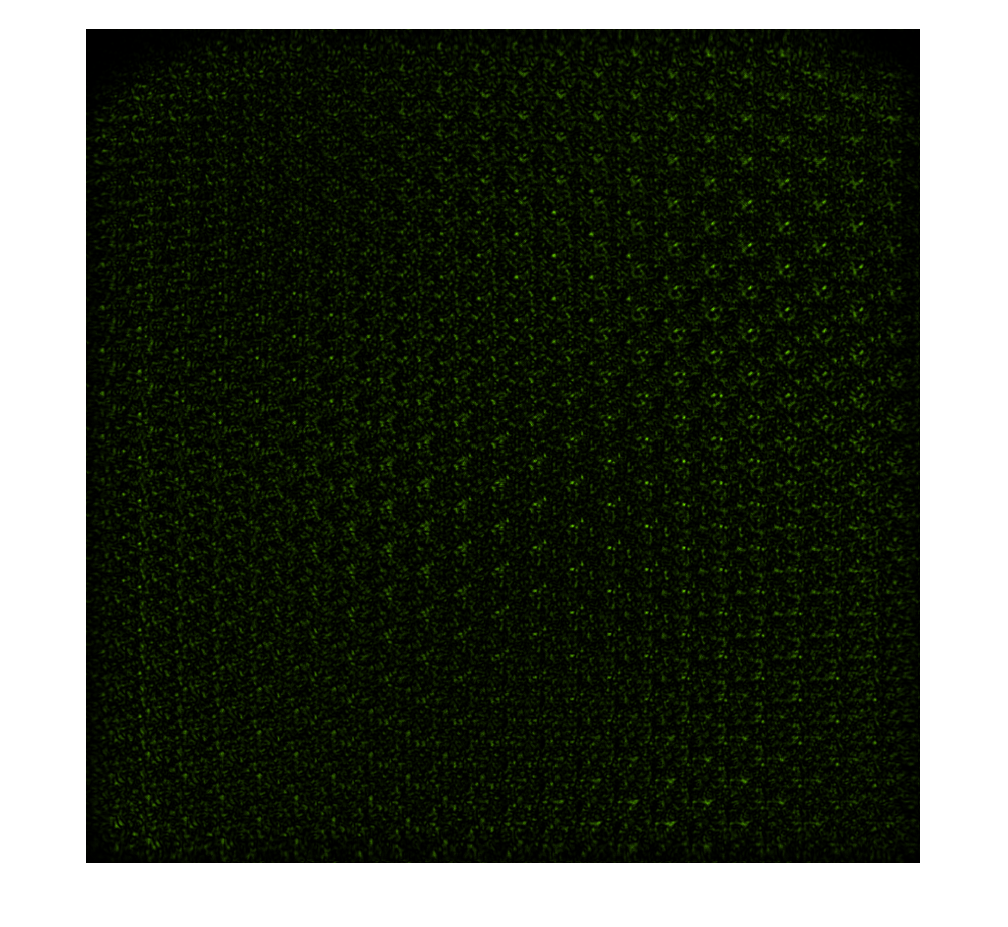

tic
for ii=1:times
    %叠加随机相位
    beamss=beams+beamAmp*noise*randn(size(beams));
    F = transform(beamss, area1, lambda, 20, [rate, rate]);
    index=round((velocity*(ii-1)*deltat)/rate+1);
    F=F.*phase(index:index+size(F,1)-1,:);
    F = transform(F, area1, lambda, 50, [rate, rate]);
    afterLens=ASMinLens(F,MLA1,lambda,area1);
    F = transform(afterLens, area2, lambda, distance1, [rate, rate]);
    afterLens = ASMinLens(F,FL,lambda,area2);
    F = transform(afterLens, area2, lambda, distance2, [rate, rate]);
    %afterLens = ASMinLens(F,MLA2,lambda,area2);
    %F = transform(afterLens, area2, lambda, distance3, [rate, rate]);
    %F=F.*aperture;
    %F=FT2Dc(F);
    %F=mask.*F;
    %F=IFT2Dc(F);


    I_now=abs(F).^2;
    if ii==1
        I=I_now;
    else
        I=I+I_now;
    end
    %disp(ii)
    %subplot(2,2,1.5)
    Inorm=(I-min(I,[],'all'))./(max(I,[],'all')-min(I,[],'all'));
    imshow(uint16(Inorm*65536),mymap)
    Inorm=gather(Inorm);
    %{
    if mod(ii,20)==0
        [meanFWHM,radius]=calMeanDia(Inorm,gather(ceil(d_ex/rate)*0.75),0.5);
        disp(['平均FWHM=' num2str(meanFWHM*1e6*rate3) 'nm'])
        peakmap=findPeak(Inorm);
        [row,~]=find(peakmap==1);
        disp(['光点数：' num2str(size(row,1))]);
        Im=Inorm(peakmap);
        uniformity(end+1)=1-(max(Im)-min(Im))./(max(Im)+min(Im));
        %plot(uniformity)
    end
    %}
    %{
    hist=imhist(Inorm);
    [~,peak(end+1)]=max(hist);
    SD(end+1)=std(Inorm,0,'all');
    subplot(2,2,3)
    plot(peak)
    subplot(2,2,4)
    plot(SD)
    %}
    drawnow
    disp(['积分时间' num2str(ii*deltat) 'μs,已完成' num2str(ii/times*100) '%']);
end

imwrite(double(Inorm),'spotArray_hexagon.tiff','tiff')